# Esercizio 2

## Dato la seguente Fdt $G(s)=\frac{1}{s(s+3.5)^3}$ progettare un controllore digitale tale:

- **Errore massimo del 4% rispetto ad un disturbo d(t) di carico modellato come un gradino unitario**

- **Sovra-elongazione percentuale massima pari al 15% e tempo di salita minore di 2 sec**

### **0.Osservazioni preliminari:**

L'impianto da controllare ha le seguenti caratteristiche

clc
clear
close all
s=tf('s');
Gs=1/(s*(s+3.5)^3)

Gs =
 
                   1
  ------------------------------------
  s^4 + 10.5 s^3 + 36.75 s^2 + 42.88 s
 
Continuous-time transfer function.
Model Properties


pole(Gs)

ans =    0.0000 + 0.0000i
  -3.5000 + 0.0000i
  -3.5000 + 0.0000i
  -3.5000 - 0.0000i


zero(Gs)


ans =

  0×1 empty double column vector



Prima di inizare bisogna considerare la presenza del ricostruttore nel modello dell'impianto. 

Quindi la funzione di trasferimento su cui lavoreremo sarà $P(s)=\frac{1}{T_s}H(s)G(s)$ dove $H(s)=\frac{T_s}{1+\frac{T_s}{2}s}$

Ts = 0.12;%tr/20<=<Ts=tr/10
Ps = 1/(1+s*Ts/2)*Gs

Ps =
 
                            2
  -----------------------------------------------------
  0.12 s^5 + 3.26 s^4 + 25.41 s^3 + 78.64 s^2 + 85.75 s
 
Continuous-time transfer function.
Model Properties


pole(Ps)

ans =    0.0000 + 0.0000i
 -16.6667 + 0.0000i
  -3.5000 + 0.0000i
  -3.5000 - 0.0000i
  -3.5000 + 0.0000i


Si noti come il sistema sia un sistema di tipo 1, poche contiene un polo nell'origine. Gli altri poli presenti sono tutti nella regione di convergenza dunque non creano particolari problemi, ma come ben sappiamo potrebbero eserci problemi nel sistema retroazionato...

### **1:**

La prima specifica che ci viene richiesta dal nostro problema è quella di gestire un errore massimo(dunque a regime) inferiore al 4%, avendo un distrubo di carico $d(t)=1(t) \to D(s)=\frac{1}{s}$

Ricordiamo che le ipotesi di LTI ci permettono di  esprimere l'uscita del sistema come : $y(t) = y_r(t) + y_{do}(t) + y_{di} (t) + y_n(t)$

- yr(t) rappresenta l’uscita ideale dello schema di controllo nell’ipotesi che disturbi e rumori di misura siano assenti. Nella sezione precedente ne abbiamo studiato le caratteristiche rapportandoci all’errore di inseguimento;

- ydo(t) rappresenta l’effetto che il disturbo posizionato sull’uscita dell’impianto da regolare ha sull’uscita dell’impianto regolato. Questa uscita si ricava ponendo a zero il riferimento, il disturbo di carico ed il rumore di misura. 

- ydi (t) rappresenta l’effetto che il disturbo posizionato sul canale di comando dell’impianto da regolare ha sull’uscita dell’impianto regolato. Questa uscita si ricava ponendo a zero il riferimento, il disturbo in uscita all’impianto da regolare ed il rumore di misura; 

- yn(t) rappresenta l’effetto che il rumore di misura ha sull’uscita dell’impianto regolato. Questa uscita si ricava ponendo a zero il riferimento, il disturbo di carico ed il disturbo in uscita all’impianto da regolare

Dalla teoria sappiamo che la L-trasformata del gradino è $D(s)=\frac{D_o}{s}$, ma il nostro sistema è di tipo 1.

Ho bisogno di un controllore del tipo $C(s)=Ks$ per far diventare la funzione ad anello L di tipo zero poiche so:

- se la funzione di anello `e di tipo 0 allora tale errore potra essere reso arbitrariamente piccolo ma mai nullo scegliendo un valore elevato della costante di posizione K,

$lim_{t \to \infty}y_D(t)<0.04 \rightarrow  lim_{s \to 0} s\frac{G(s)}{1+C(s)G(s)}\frac{D_o}{s}=> y_{D,\infty}=\lim_{s\rightarrow 0}s\frac{\frac{\tilde{G}(s)}{s}}{1+K\frac{\tilde{G}(s)}{s}}\frac{1}{s}\leq 0.04$ 51

Dopo una serie di passi ottengo : $K \geq 25$, consideranod il gradino unitario come disturbo $D(s)=\frac{1}{s}$, 

K=25.7;
Cs=K;
Ls=Cs*Ps

Ls =
 
                          51.4
  -----------------------------------------------------
  0.12 s^5 + 3.26 s^4 + 25.41 s^3 + 78.64 s^2 + 85.75 s
 
Continuous-time transfer function.
Model Properties


Visualizzaimo la risposta al gradino a ciclo chiuso

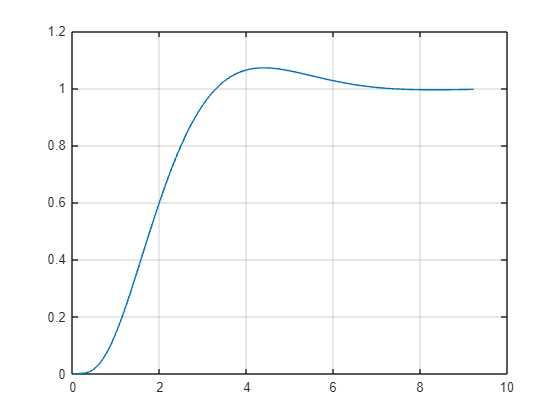


figure
[y,t]=step(feedback(Ls,1));
plot(t,y)
grid

stepinfo(feedback(Ls,1))

ans = struct with fields:
         RiseTime: 1.9536
    TransientTime: 6.2105
     SettlingTime: 6.2105
      SettlingMin: 0.9032
      SettlingMax: 1.0716
        Overshoot: 7.1568
       Undershoot: 0
             Peak: 1.0716
         PeakTime: 4.4046


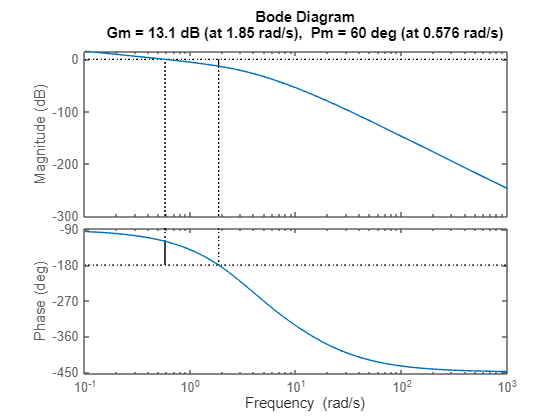

margin(Ls)

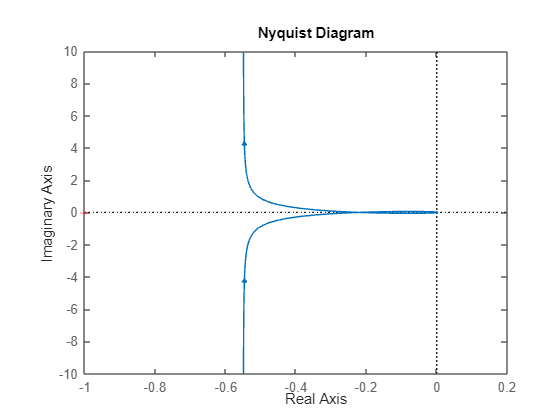

nyquist(Ls)

### 2:

Dalla specifica sulla sovraelongazione ricavo lo smorzamento desiderato pari a $\delta=\frac{1}{\sqrt{1+\left(\frac{\pi}{\log(S)}\right)^2}}$

S=0.08;%dalla specifica di sovraelongazione 
d = 1/sqrt(1+(pi/log(S))^2) % fattore di smorzamento desiderato

d = 0.6266

phi_m = 100*d %fase desiderata per le specifiche

phi_m = 62.6577

tr = 2; 
omega_b=(0.8*pi)/(tr) %pulasazione banda passante

omega_b = 1.2566

omega_c=1.26;%(siccome phi_m<90 -> (omega_c >=omega_b)
[M,phi] =bode(Ls,omega_c)

M = 0.3951

phi = -153.7200

phi_corrente = 180-abs(phi)

phi_corrente = 26.2800

Condizioni per una rete anticipatrice


m = 1/M %incremento di guadagno

m = 2.5308

theta= phi_m-phi_corrente %incremento di fase ammissibile

theta = 36.3777

alpha =(m*cos(deg2rad(theta))-1)/(m*(m-cos(deg2rad(theta)))) %aplha e T devono essere sempre positivi

alpha = 0.2376

T = (1/omega_c)*sqrt((1-m^2)/(alpha^2*m^2-1))

T = 2.3092

Clead = (1+s*T)/(1+s*alpha*T)

Clead =
 
  2.309 s + 1
  ------------
  0.5486 s + 1
 
Continuous-time transfer function.
Model Properties


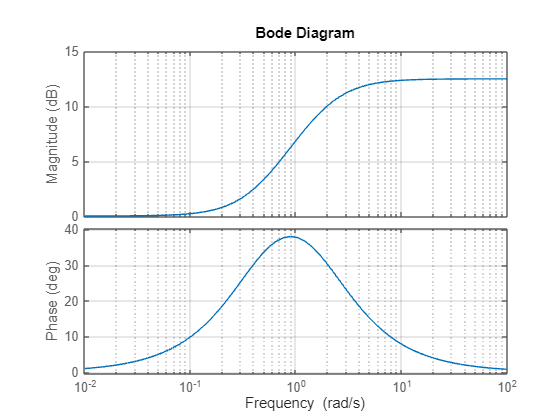

figure
bode(Clead)
grid

Ls=Clead*Ls

Ls =
 
                             118.7 s + 51.4
  --------------------------------------------------------------------
  0.06584 s^6 + 1.909 s^5 + 17.2 s^4 + 68.56 s^3 + 125.7 s^2 + 85.75 s
 
Continuous-time transfer function.
Model Properties


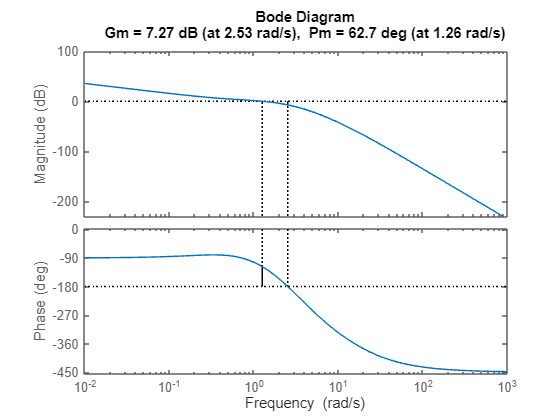

margin(Ls)

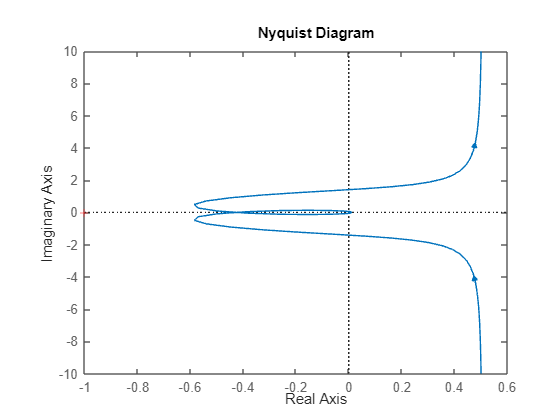

nyquist(Ls)

Fs = minreal(feedback(Ls,1))

Fs =
 
                            1803 s + 780.7
  ------------------------------------------------------------------
  s^6 + 28.99 s^5 + 261.3 s^4 + 1041 s^3 + 1909 s^2 + 3105 s + 780.7
 
Continuous-time transfer function.
Model Properties


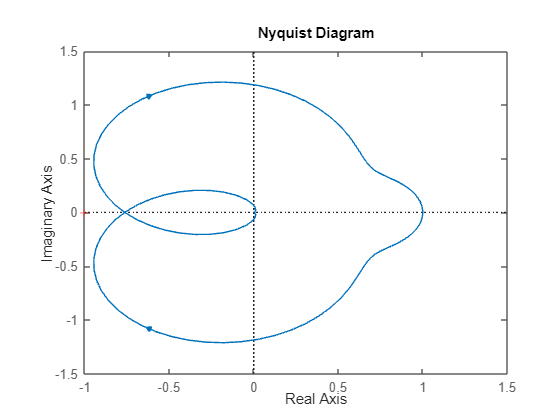

nyquist(Fs)

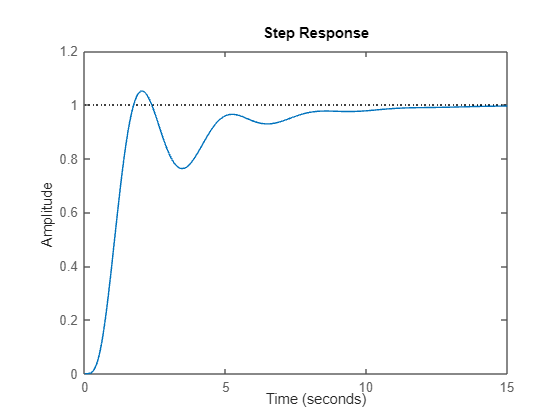


step(Fs)

stepinfo(Fs)

ans = struct with fields:
         RiseTime: 0.9592
    TransientTime: 10.1997
     SettlingTime: 10.1997
      SettlingMin: 0.7633
      SettlingMax: 1.0519
        Overshoot: 5.1863
       Undershoot: 0
             Peak: 1.0519
         PeakTime: 2.0366


[nump,denp]=tfdata(Gs,'v')

nump =      0     0     0     0     1


denp =     1.0000   10.5000   36.7500   42.8750         0


Cs=Cs*Clead

Cs =
 
  59.35 s + 25.7
  --------------
   0.5486 s + 1
 
Continuous-time transfer function.
Model Properties


[numc,denc]=tfdata(Cs,'v')

numc =    59.3474   25.7000


denc =     0.5486    1.0000


z=tf('z');
s=(z-1)/(Ts);
Cs_eul_avanti =  minreal((59.35*s + 25.7)/(0.546*s + 1));
[num1,den1]=tfdata(Cs_eul_avanti,'v');
s=(z-1)/(z*Ts);
Cs_eul_indietro =  minreal((59.35*s + 25.7)/(0.546*s + 1));
[num2,den2]=tfdata(Cs_eul_indietro,'v');

Cs_tustin = c2d(Cs,Ts,'tustin');
[num3,den3]=tfdata(Cs_tustin,'v');